# Ordinær eksamen Januar 2019

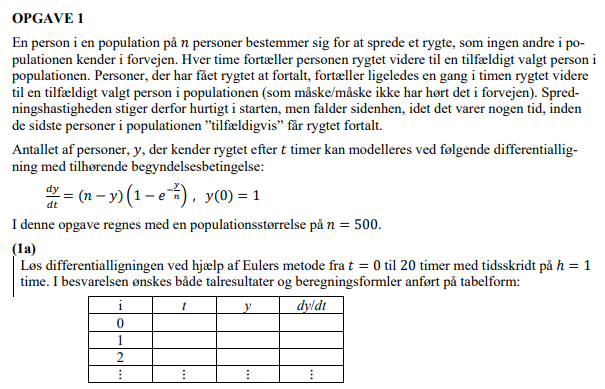

t = linspace(0,20,21);
n = 500;
arr = [];
arr1 = [];
arr2 = [];
for i=0:20
    if i == 0;
        y = 1;
        arr(end+1) = y;
        dydt = (n-y).*(1-exp(-y/n));
        arr1(end+1) = dydt;
    else i>0;
        yold = y;
        ynew = yold + dydt;
        arr(end+1) = ynew;
        dydt = (n-ynew)*(1-exp(-ynew/n));
        arr1(end+1) = dydt;
        y = ynew;
    end
end
varNames = {'t', 'y', 'dydt'};
rootTable = table(t',arr', arr1','VariableNames',varNames)

rootTable = 21×3 table
    t       y        dydt  
    __    ______    _______

     0         1      0.997
     1     1.997     1.9851
     2    3.9821     3.9347
     3    7.9167       7.73
     4    15.647     14.922
     5    30.569      27.84
     6     58.41     48.687
     7     107.1     75.755
     8    182.85      97.14
     9    279.99     94.336
    10    374.33     66.229
    11    440.56     34.815
    12    475.37     15.111
    13    490.48     5.9492
    14    496.43     2.2465
    15    498.68    0.83455


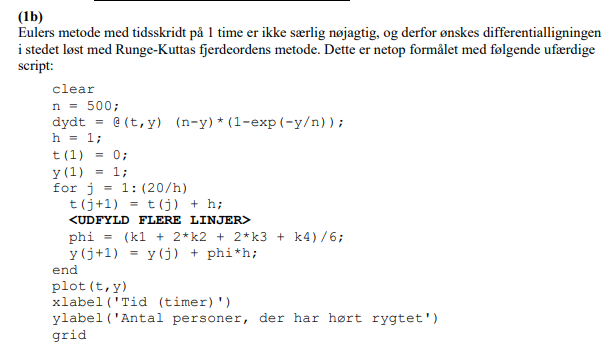

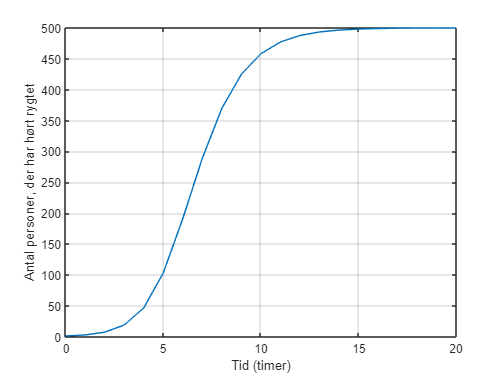

clear
n = 500;
dydt = @(t,y) (n-y)*(1-exp(-y/n));
h = 1;
t(1) = 0;
y(1) = 1;
for j = 1:(20/h)
 t(j+1) = t(j) + h;
 k1 = dydt(t(j),y(j));
 tmid1 = t(j) + h/2;
 Ymid1 = y(j) + k1*h/2;
 k2 = dydt(tmid1,Ymid1);
 tmid2 = t(j) + h/2;
 Ymid2 = y(j) + k2*h/2;
 k3 = dydt(tmid2,Ymid2);
 tend = t(j) + h;
 Yend = y(j) + k3*h;
 k4 = dydt(tend,Yend);
 phi = (k1 + 2*k2 + 2*k3 + k4)/6;
 y(j+1) = y(j) + phi*h;
end
plot(t,y)
xlabel('Tid (timer)')
ylabel('Antal personer, der har hørt rygtet')
grid

## Opgave 2:

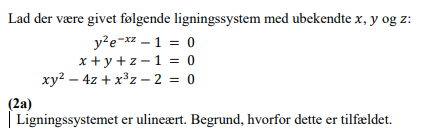

Dette er tilfældet da henholdsvis ligning 1 & 3 er et funktions udtryk for en ikke lineær ligning.

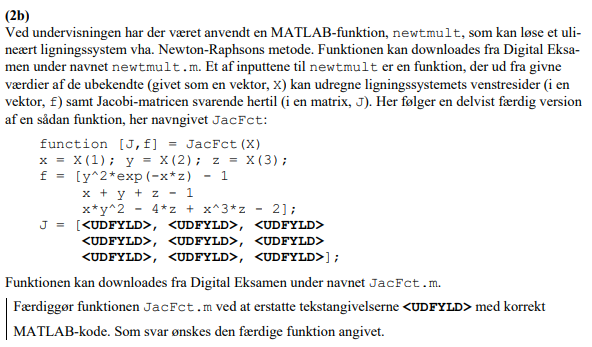

clear
syms x y z;
f = [y^2*exp(-x*z) - 1 
     x + y + z - 1 
     x*y^2 - 4*z + x^3*z - 2]; 
J = jacobian(f)

$$J = \left(\begin{array}{ccc} -y^{2}\,z\,{\mathrm{e}}^{-x\,z} & 2\,y\,{\mathrm{e}}^{-x\,z} & -x\,y^{2}\,{\mathrm{e}}^{-x\,z}\\ 1 & 1 & 1\\ 3\,z\,x^{2}+y^{2} & 2\,x\,y & x^{3}-4 \end{array}\right)$$

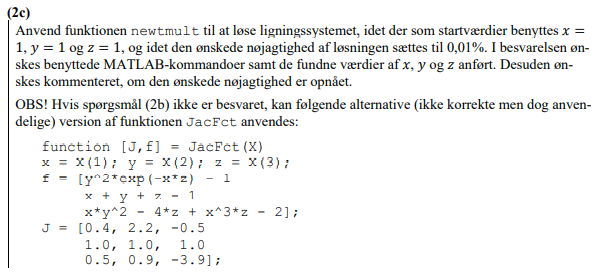

[x,f,ea,iter] = newtmult(@JacFct,[1;1;1],0.0001)

x =     0.5094
    0.9008
   -0.4102


f = 1.0e-06 *

    0.0190
   -0.0000
   -0.1099


ea = 1.0235e-05

iter = 7

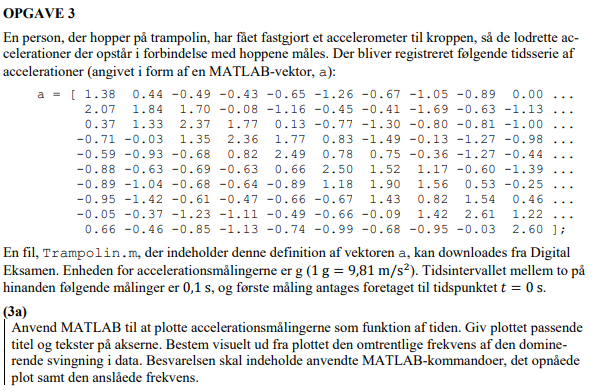

a = [ 1.38 0.44 -0.49 -0.43 -0.65 -1.26 -0.67 -1.05 -0.89 0.00 ...  
    2.07 1.84 1.70 -0.08 -1.16 -0.45 -0.41 -1.69 -0.63 -1.13 ...  
    0.37 1.33 2.37 1.77 0.13 -0.77 -1.30 -0.80 -0.81 -1.00 ...  
    -0.71 -0.03 1.35 2.36 1.77 0.83 -1.49 -0.13 -1.27 -0.98 ...  
    -0.59 -0.93 -0.68 0.82 2.49 0.78 0.75 -0.36 -1.27 -0.44 ...  
    -0.88 -0.63 -0.69 -0.63 0.66 2.50 1.52 1.17 -0.60 -1.39 ...  
    -0.89 -1.04 -0.68 -0.64 -0.89 1.18 1.90 1.56 0.53 -0.25 ...  
    -0.95 -1.42 -0.61 -0.47 -0.66 -0.67 1.43 0.82 1.54 0.46 ...  
    -0.05 -0.37 -1.23 -1.11 -0.49 -0.66 -0.09 1.42 2.61 1.22 ...  
    0.66 -0.46 -0.85 -1.13 -0.74 -0.99 -0.68 -0.95 -0.03 2.60]; % 100 målinger
t = linspace(0,9.9,100); % Tidintervallet for de 100 målinger
plot(t,a)
xlabel("Tiden")
ylabel("Tyngdeaccelerationen af hopper paa trampolin")

Der er talt 9 toppe over en periode af 10 sekunder: $frekvens = \frac{9}{10 sek} = 0.9 Hz$

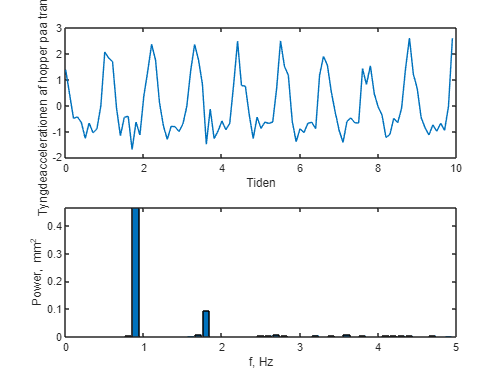

y = a;                      % Vores datasæt
%% -------------------------------------------------
dt = 0.1;                   % Samplingsinterval (s)
n = length(y);              % Antal samplinger
T = n*dt;                   % Signallængde (s)
t = (0:n-1)*dt;             % Tidsvektor (s)
Y = fft(y)/n;               % FFT af y (mm)
fs = 1/dt;                  % Samplingsfrekvens (Hz)
fmax = fs/2;                % Maks frekvens (Hz)
df = 1/T;                   % Frekvensstep (Hz)
f = (0:n-1)*df;             % Frekvensvektor (Hz)
P = real(Y).^2 + imag(Y).^2;% Powervektor
subplot(2,1,2)
bar(f,P);                   % Plot af powerspektrum
xlim([0 fmax]);             % Afgræns frekvensakse
xlabel('f, Hz'), ylabel('Power, mm^2')

res = find(P==max(P)) % Finder punkterne hvor vores tyngdeacceleration er størst

res =     10    92


FFT = f(res(1))       % Bestemmer frekvensen for den første af de to fundne peaks.

FFT = 0.9000

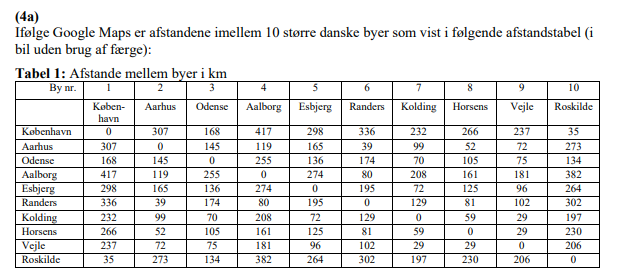

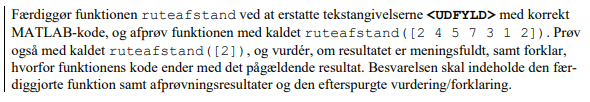

bynr = [2 4 5 7 3 1 2];
atbl = [ 0 307 168 417 298 336 232 266 237 35
 307 0 145 119 165 39 99 52 72 273
 168 145 0 255 136 174 70 105 75 134
 417 119 255 0 274 80 208 161 181 382
 298 165 136 274 0 195 72 125 96 264
 336 39 174 80 195 0 129 81 102 302
 232 99 70 208 72 129 0 59 29 197
 266 52 105 161 125 81 59 0 29 230
 237 72 75 181 96 102 29 29 0 206
 35 273 134 382 264 302 197 230 206 0];
n = length(bynr);
afstand = 0;
for i = 1:n-1
    %disp(atbl(bynr(i),bynr(i+1)))
    %disp(i)
    %disp(i+1)
    afstand = afstand + atbl(bynr(i),bynr(i+1));
end